fs = 6000;
T = 0.5;
t = 0:1/fs:T-1/fs;

frequency = 525;
n = 4*sin(2*pi*frequency*t) + 0.02*sin(2*pi*1300*t) ...
+ 0.02*sin(2*pi*1600*t) + 0.02*sin(2*pi*1800*t) ...
+ 0.02*sin(2*pi*2100*t) + 0.02*sin(2*pi*2300*t) ...
+ 0.02*sin(2*pi*2650*t) + 0.02*sin(2*pi*2850*t);
T0 = length(n)/fs; 
delta_f = 1/T0;

function [Y, freq] = make_spectrum(signal, fs)
Y = fft(signal);
Y = Y/(length(Y));

delta_f = fs/length(signal);
f_pos = 0:delta_f:fs/2;
f_neg = -fs/2+delta_f:delta_f:-delta_f;
freq = [f_pos f_neg];
end

[y, fs_y] = audioread('New Recording 6.m4a');

%Transformation of Audio Dataset
amp = y(80000:103999, :); % Taking a 0,5 second snippet of the recording
disp(length(amp)) % Should be 24000 because audio has a 48000 sampling frequency

       24000



amp_new = amp(1:8:end); % Taking a sample at a rate of 6000Hz
disp(length(amp_new)); % Should be 3000

        3000



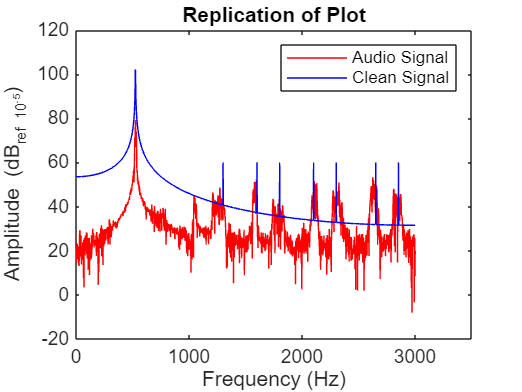


[Y_audio, freq_audio] = make_spectrum(amp_new, fs);
[Y, freq] = make_spectrum(n, fs);

%Changing to only positive values
Y_audio = Y_audio(1:1500,:);
Y = Y(:, 1:1500);
freq_audio = freq_audio(:,1:1500);
freq = freq(:,1:1500);

%Plot Part 1
h = [];
new_h = plot(freq_audio,20*log10(abs(Y_audio)*100000),'r', 'DisplayName','Audio Signal');
h(end+1) = new_h(1);
hold on
new_h = plot(freq, 20*log10(abs(Y)*100000),'b', 'DisplayName','Clean Signal');
h(end+1) = new_h(1);
legend(h);
title('Replication of Plot')
xlabel('Frequency (Hz)')
ylabel('Amplitude (dB_{ref 10^{-5}})')
xlim([0 3500])

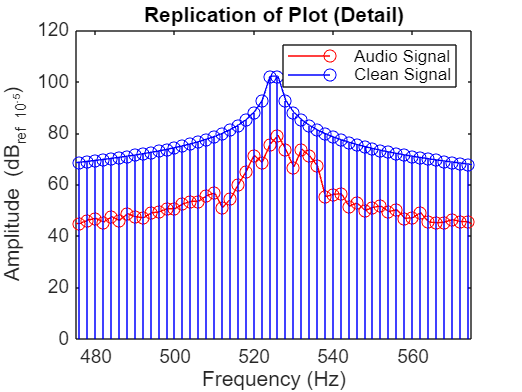

%Plot Part 2
h = [];
new_h = stem(freq_audio,20*log10(abs(Y_audio)*100000),'r', 'DisplayName','Audio Signal');
h(end+1) = new_h(1);
hold on
new_h = stem(freq, 20*log10(abs(Y)*100000),'b', 'DisplayName','Clean Signal');
h(end+1) = new_h(1);
legend(h);

title('Replication of Plot (Detail)')
xlabel('Frequency (Hz)')
ylabel('Amplitude (dB_{ref 10^{-5}})')
xlim([475 575])